% ex1Vout1 = 'Ex1_Vout1new.csv';
% ex1Vout1 = csvread(ex1Vout1);
% ex1Vout2 = 'Ex1_Vout2new.csv';
% ex1Vout2 = csvread(ex1Vout2);
% ex1Vout3 = 'Ex1_Vout3new.csv';
% ex1Vout3 = csvread(ex1Vout3);
% ex1Vout4 = 'Ex1_Vout2new.csv';
% ex1Vout4 = csvread(ex1Vout4);
% 
% % ex1In1 = csvread('Ex1_In1.csv');
% % ex1In2 = csvread('Ex1_In2.csv');
% % ex1In3 = csvread('Ex1_In3.csv');
% % ex1In4 = csvread('Ex1_In4.csv');
% ex1In = logspace(log10(.0001), log10(.00000001), 100);
%  
% plot(ex1In,ex1Vout1); 
% hold on;
% plot(ex1In,ex1Vout2)
% plot(ex1In,ex1Vout3)
% plot(ex1In,ex1Vout4)
% hold off;

% Data for each transistor
Vg = {ex1Vout1, ex1Vout2, ex1Vout3, ex1Vout4};
Isat = {ex1In, ex1In, ex1In, ex1In};

Is_array = zeros(1, 4);
VT_array = zeros(1, 4);
kappa_array = zeros(1, 4);

for i = 1:4
    [Is_array(i), VT_array(i), kappa_array(i)] = ekvfit(Vg{i}, Isat{i}, 1e-3, 'off');
end
fprintf('Transistor | Is (A) | VT (V) | kappa\n');1

Transistor | Is (A) | VT (V) | kappa


ans = 1

for i = 1:4
    fprintf('%10d | %8.4e | %6.4f | %6.4f\n', i, Is_array(i), VT_array(i), kappa_array(i));
end

         1 | 1.8209e-06 | 0.6568 | 0.6702
         2 | 1.7379e-06 | 0.6521 | 0.6696
         3 | 1.7796e-06 | 0.6550 | 0.6711
         4 | 1.7379e-06 | 0.6521 | 0.6696


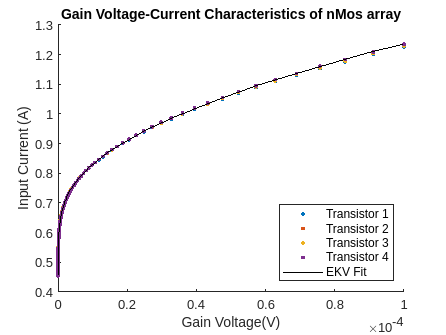


% Plot voltage-current characteristics along with one of the fits
figure;
hold on;
for i = 1:4
    semilogy(Isat{i},Vg{i}, '.', 'DisplayName', sprintf('Transistor %d', i));
end
legend('Location','southeast');
xlabel('Gain Voltage(V)');
ylabel('Input Current (A)');
title('Gain Voltage-Current Characteristics of nMos array');

% Fit EKV model to one of the transistors
fit_transistor = 2; % Change this index to select a different transistor for fitting
fit_Is = Is_array(fit_transistor);
fit_VT = VT_array(fit_transistor);
fit_kappa = kappa_array(fit_transistor);
fit_Isat = fit_Is * (log(1 + exp(fit_kappa * (Vg{fit_transistor} - fit_VT) / (2 * 0.0258)))).^2;
semilogy( fit_Isat,Vg{fit_transistor}, 'k-', 'DisplayName', 'EKV Fit');
legend;

print("-depsc","voltage-current.eps")

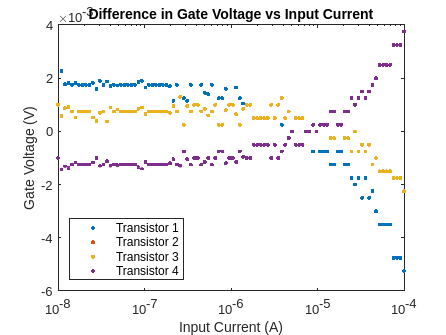


% Plot difference between gate voltage and average gate voltage
avg_Vg = (Vg{1}+Vg{2}+Vg{3}+Vg{4})/4;
figure;
for i = 1:4
    diff_Vg = Vg{i} - avg_Vg;
    semilogx(Isat{i}, diff_Vg, '.', 'DisplayName', sprintf('Transistor %d', i));
    hold on;
end

xlabel('Input Current (A)');
ylabel('Gate Voltage (V)');
title('Difference in Gate Voltage vs Input Current');
legend('Location','southwest');
print("-depsc","exp1plot2.eps")

%ekvfit()

% Extracting incremental transconductance gain
% Select the transistor for which you want to extract the gain
selected_transistor = 2;

% Compute the finite-difference approximation of transconductance gain
delta_Vg = diff(Vg{selected_transistor});
delta_Isat = diff(Isat{selected_transistor});
gm = delta_Isat ./ delta_Vg;
1

ans = 1

kappa_t = 0.68;
u_tt = 0.025;
I_s_t = 1.7e-6;
I_sat_t = logspace(log10(.0001), log10(.00000001), 100);
gm_theo = (kappa_t ./ u_tt) .* sqrt(I_s_t .* I_sat_t).*(1-(exp(-(sqrt(I_sat_t ./ I_s_t)))))

gm_theo = 1.0e-03 *

    0.3545    0.3383    0.3228    0.3081    0.2939    0.2804    0.2675    0.2551    0.2432    0.2318    0.2209    0.2105    0.2004    0.1908    0.1815    0.1726    0.1641    0.1559    0.1480    0.1404    0.1331    0.1261    0.1194    0.1129    0.1067    0.1008    0.0951    0.0896    0.0844    0.0795    0.0747    0.0702    0.0659    0.0618    0.0579    0.0542    0.0507    0.0473    0.0442    0.0412    0.0384    0.0358    0.0333    0.0310    0.0288    0.0267    0.0248    0.0230    0.0213    0.0197


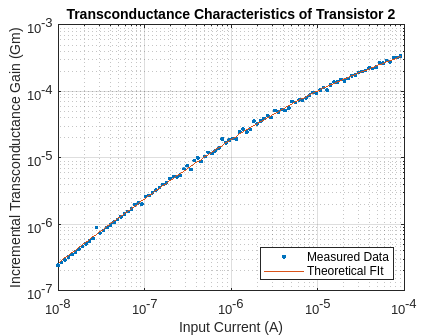

gm_theo = gm_theo(2:end);
% Plotting the incremental transconductance gain
figure;
loglog(Isat{selected_transistor}(2:end), gm,'.', 'DisplayName', 'Measured Data');
hold on;
loglog(Isat{selected_transistor}(2:end), gm_theo, 'DisplayName', 'Theoretical FIt');
% Theoretical fit (optional)
% You can fit a model to the measured data and plot it here

xlabel('Input Current (A)');
ylabel('Incremental Transconductance Gain (Gm)');
title('Transconductance Characteristics of Transistor 2');
legend('Location','southeast');grid on;
hold off;
print("-depsc","exp1plot3.eps")

%
% LINEFIT Fits tries to fit a line to an appropriate part of a given curve.
%    LINEFIT(X, Y, EPSILON) steps through the curve specified by vectors
%    X and Y searching for a consecutive run of at least 10 coordinate
%    pairs to which a straight line can be fit using linear regression with
%    an R^2 (i.e., goodness of fit) value of greater than 1-EPSILON.  If
%    there are more than one such run of points, the one with the steepest
%    slope is used.  A typical value for EPSILON is in the range of 5e-4 to
%    5e-3.  The return values are [FIRST, LAST, MMAX, BMAX, NMAX], where
%
%        FIRST is the index of the first point used in the fit,
%        LAST is the index of the last point used in the fit,
%        MMAX is the slope of the best fit line,
%        BMAX is the y-axis intercept of the best-fit line, and
%        NMAX is the number of points used in the fit.

function [first, last, mmax, bmax, Nmax]=linefit(x, y, epsilon)

first=0;
last=0;
mmax=0;
bmax=0;
Nmax=0;

i=1;
while i<length(x),
    R2=1;
    N=1;
    sumX=x(i);
    sumX2=x(i)*x(i);
    sumY=y(i);
    sumY2=y(i)*y(i);
    sumXY=x(i)*y(i);
    j=i;
    while (j<length(x)) & (R2>1-epsilon),
        j=j+1;
        N=N+1;
        sumX=sumX+x(j);
        sumX2=sumX2+x(j)*x(j);
        sumY=sumY+y(j);
        sumY2=sumY2+y(j)*y(j);
        sumXY=sumXY+x(j)*y(j);
        SXX=sumX2-sumX*sumX/N;
        SYY=sumY2-sumY*sumY/N;
        SXY=sumXY-sumX*sumY/N;
        m=SXY/SXX;
        b=(sumY-m*sumX)/N;
        R2=SXY*SXY/(SXX*SYY);
    end
    if ((N>10) & (abs(m)>abs(mmax))),
        first=i;
        last=j;
        mmax=m;
        bmax=b;
        Nmax=N;
    end
    i=j;
end
end

ekv

%
% EKVFIT Attempts to fit a simplified EKV model to (VG, ISAT) pairs.
%    EKVFIT(VG, ISAT, EPSILON) attempts to fit a simplified EKV model for
%    the saturation region of MOS transistor operation to measured values
%    of gate voltage (specified in VG) and channel current (specified in
%    ISAT).  The assumed form of the model is
%
%        ISAT = Is * (log(1 + exp(kappa*(VG - VT)/(2*0.0258)))).^2
%
%    The return values are [Is, VT, kappa].  EKVFIT makes use of LINEFIT.
%    First, it attempts to find parameters for the weak-inversion region by
%    using LINEFIT on VG and log(ISAT).  Then, it attepts to find
%    parameters for the strong-inversion region by using LINEFIT on VG and
%    sqrt(ISAT).  It then uses the x-axis intercept from the
%    strong-inversion fit as a starting value for VT and computes a
%    starting value for IS via cubic-spline interpolation as twice the
%    value of ISAT when VG = VT.  EKVFIT then attepts to find a the value
%    of IS in the interval between one tenth the initial value of IS and
%    ten times the inital value of IS that minimizes the curvature of the
%    inverse EKV model applied to ISAT, given by
%
%                     log(exp(sqrt(ISAT/Is)) - 1),
%
%    when plotted as a function of VG, using the golden-section search.
%    Once the best value of Is is found, EKVFIT uses LINEFIT to get the
%    slope and intercept of the best-fit line to the EKV model inverse
%    expression, given above, applied to ISAT versus VG.  The slope of this
%    curve should be kappa/(2*UT) and the VG-axis intercept should be VT.
%
%    See the LINEFIT help comment for an explanation of the EPSILON 
%    parameter.
%
function [Is, VT, kappa]=ekvfit(Vg, Isat, epsilon, varargin)

if nargin==3,
    plotting = 'off';
else
    plotting = varargin(1);
end

Is = 0;
VT = 0;
kappa = 0;

[WIfirst, WIlast, WIm, WIb, WIN]=linefit(Vg, log(Isat), epsilon);
if WIN==0
    error('Could not find a weak-inversion region.');
elseif strcmp(plotting, 'on')==1
    semilogy(Vg, Isat);
    temp = axis;
    semilogy(Vg, Isat, 'b.', Vg(WIfirst:WIlast), Isat(WIfirst:WIlast), 'r.', Vg, exp(WIm*Vg + WIb), 'k-');
    axis(temp);
    xlabel('{\it V}_G (V)');
    ylabel('{\it I}_{sat} (A)');
    title('Weak-Inversion Fit');
    pause;
end
if min(abs(Isat(WIfirst:WIlast)))>1e-6
    error('Identified a candidate weak-inversion region, but all current levels exceed typical weak-inversion currents.');
end
if max(abs(Isat(WIfirst:WIlast)))>1e-6
    warning('Identified a candidate weak-inversion region, but some current levels exceed typical weak-inversion currents.');
end

[SIfirst, SIlast, SIm, SIb, SIN]=linefit(Vg, sqrt(Isat), epsilon);
if SIN==0
    error('Could not find a strong-inversion region.');
elseif strcmp(plotting, 'on')==1
    plot(Vg, sqrt(abs(Isat)));
    temp = axis;
    plot(Vg, sqrt(abs(Isat)), 'b.', Vg(SIfirst:SIlast), sqrt(Isat(SIfirst:SIlast)), 'r.', Vg, SIm*Vg + SIb, 'k-');
    axis(temp);
    xlabel('{\it V}_G (V)');
    ylabel('{\it I}^{1/2}_{sat} (A^{1/2})');
    title('Strong-Inversion Fit');
    pause;
end
if max(abs(Isat(SIfirst:SIlast)))<0.1e-6
    error('Identified a candidate strong-inversion region, but all current levels are lower than typical strong-inversion currents.');
end
if min(abs(Isat(SIfirst:SIlast)))<0.1e-6
    warning('Identified a candidate strong-inversion region, but some current levels are lower than typical strong-inversion currents.');
end

if SIfirst>WIlast
    first = WIfirst;
    last = SIlast;
elseif WIfirst>SIlast
    first = SIfirst;
    last = WIlast;
else
    error('Weak-inversion and strong-inversion regions found were not disjoint.');
end

VT=-SIb/SIm;
Is=2*spline(Vg(first:last), Isat(first:last), VT);

R=0.61803399;
C=1.-R;
tol=1e-4;

x0=0.1*Is;
x1=Is;
x2=(1.+9.*C)*Is;
x3=10.*Is;

dVg=diff(Vg(first:last));
temp=diff(log(exp(sqrt(Isat(first:last)/x1))-1))./dVg;
f1=std(temp)/mean(temp);
temp=diff(log(exp(sqrt(Isat(first:last)/x2))-1))./dVg;
f2=std(temp)/mean(temp);

while abs(x3-x0)>tol*(abs(x1)+abs(x2)),
    if f2<f1,
        x0=x1; x1=x2; x2=R*x1+C*x3;
        f1=f2;
        temp=diff(log(exp(sqrt(Isat(first:last)/x2))-1))./dVg;
        f2=std(temp)/mean(temp);
        if strcmp(plotting, 'on')==1
            [EKVfirst, EKVlast, m, b, N]=linefit(Vg(first:last), log(exp(sqrt(Isat(first:last)/x2))-1), epsilon);
            plot(Vg(first:last), log(exp(sqrt(Isat(first:last)/x2))-1), 'b.', Vg(first:last), m*Vg(first:last)+b, 'k-');
            xlabel('{\it V}_G (V)');
            ylabel('log(exp(sqrt({\it I}_{sat}/{\it I}_s))-1)');
            title(['Optimizing Specific Current: {\it I}_s = ', num2str(x2), 'A']);
            pause;
        end
    else
        x3=x2; x2=x1; x1=R*x2+C*x0;
        f2=f1;
        temp=diff(log(exp(sqrt(Isat(first:last)/x1))-1))./dVg;
        f1=std(temp)/mean(temp);
        if strcmp(plotting, 'on')==1
            [EKVfirst, EKVlast, m, b, N]=linefit(Vg(first:last), log(exp(sqrt(Isat(first:last)/x1))-1), epsilon);
            plot(Vg(first:last), log(exp(sqrt(Isat(first:last)/x1))-1), 'b.', Vg(first:last), m*Vg(first:last)+b, 'k-');
            xlabel('{\it V}_G (V)');
            ylabel('log(exp(sqrt({\it I}_{sat}/{\it I}_s))-1)');
            title(['Optimizing Specific Current: {\it I}_s = ', num2str(x1), 'A']);
            pause;
        end
    end
end

if f1<f2,
    Is=x1;
else
    Is=x2;
end

[EKVfirst, EKVlast, m, b, N]=linefit(Vg(first:last), log(exp(sqrt(Isat(first:last)/Is))-1), epsilon);
VT=-b/m;
kappa=2*m*0.0258;
if strcmp(plotting, 'on')==1
    semilogy(Vg, Isat);
    temp = axis;
    semilogy(Vg, Isat, 'b.', Vg(first:last), Isat(first:last), 'r.', Vg, Is*(log(1+exp(kappa*(Vg-VT)/(2*0.0258)))).^2, 'k-');
    axis(temp);
    xlabel('{\it V}_G (V)');
    ylabel('{\it I}_{sat} (A)');
    title(['EKV Fit: {\it I}_s = ', num2str(Is), 'A, {\it V}_T = ', num2str(VT), 'V, \kappa = ', num2str(kappa)]);
    pause;
    plot(Vg, sqrt(abs(Isat)));
    temp = axis;
    plot(Vg, sqrt(abs(Isat)), 'b.', Vg(first:last), sqrt(Isat(first:last)), 'r.', Vg, sqrt(Is*(log(1+exp(kappa*(Vg-VT)/(2*0.0258)))).^2), 'k-');
    axis(temp);
    xlabel('{\it V}_G (V)');
    ylabel('{\it I}^{1/2}_{sat} (A^{1/2})');
    title(['EKV Fit: {\it I}_s = ', num2str(Is), 'A, {\it V}_T = ', num2str(VT), 'V, \kappa = ', num2str(kappa)]);
    pause;
end
end